# ETE 2024 Vidish Mishra

## Question 1

clear;clc;
warning('off')
disp("Question 1")

Question 1


inGuess=[0.2 0.2 0.2 0.2];
res=fsolve(@f,inGuess,optimset("Display",'off'));
disp("Steady State Concentrations of A: "+res(1)+" mol/L")

Steady State Concentrations of A: 0.13128 mol/L


disp("Steady State Concentrations of B: "+res(2)+" mol/L")

Steady State Concentrations of B: 0.074122 mol/L


disp("Steady State Concentrations of C: "+res(3)+" mol/L")

Steady State Concentrations of C: 0.09584 mol/L


disp("Steady State Concentrations of D: "+res(4)+" mol/L")

Steady State Concentrations of D: 0.50815 mol/L




function res=f(c)
    Ca=c(1);Cb=c(2);Cc=c(3);Cd=c(4);
    k1=0.01;k2=k1;k3=0.001;k4=k3;k5=k3; % Rate Constants at T=298
    Ca0=1;Cb0=1;v=1;V=5000;
    res=zeros(5,1);
    res(1)=v/V*(Ca0-Ca)-k1*Ca*Cb-k3*Ca*Cd-k4*Ca*Cb;
    res(2)=v/V*(Cb0-Cb)-k1*Ca*Cb-k2*Cc*Cb-k4*Ca*Cb-k5*Cc*Cb;
    res(3)=-v/V*(Cc)-k2*Cc*Cb-k5*Cc*Cb+k1*Ca*Cb;
    res(4)=-v/V*(Cd)+k1*Ca*Cb+k2*Cc*Cb-k3*Ca*Cd;
end


## Question 2

clear;clc;
warning('off')
disp("Question 2")

Question 2


inGuess=[400 335 1.3 0.6];
A=[1 0 0 0
    0 1 0 0
    0 0 1 1];
b=[10000;335;2];
lb=[10 298 0 0];
ub=[10000 335 2 2];

options = optimoptions('fmincon','Display','off','Algorithm','sqp');
[x,res1]=fmincon(@funcVT,inGuess,A,b,[],[],lb,ub,[],options);


disp("Optimal Volume: "+x(1)+"L")

Optimal Volume: 478.8955L


disp("Optimal Temp: "+x(2)+"K")

Optimal Temp: 298K


disp("Concentration of Ca0 is "+x(3)+" mol/m^3");

Concentration of Ca0 is 1.3515 mol/m^3


disp("Concentration of Cb0 is "+x(4)+" mol/m^3");

Concentration of Cb0 is 0.64845 mol/m^3


disp("Maximum Concentration of component C reached is: "+(-res1)+" mol/m^3")

Maximum Concentration of component C reached is: 0.24913 mol/m^3



function res1=funcVT(p) % Here we are passing V,T,Ca0,Cb0 as inputs
    V=p(1);T=p(2);ca0=p(3);cb0=p(4);
    m1=(0.02-0.01)/(310-298);cons1=(0.02)-m1*310;
    m2=(0.005-0.001)/(310-298);cons2=(0.005)-m2*310;
    k1=m1*T+cons1;k2=k1; % k1 as a function of Temperature
    k3=m2*T+cons2;k4=k3;k5=k3;% k3 as a function of Temperature
    k=[k1 k2 k3 k4 k5];
    inGuess=[0.2 0.2 0.2 0.2];
    res0=fsolve(@(c)f2(c,k,V,ca0,cb0),inGuess,optimset("Display",'off')); %Solving for concentration
    res1=-res0(3); % We have to maximize conc(C) which is at third index.
end

function res=f2(c,k,V,Ca0,Cb0)
    Ca=c(1);Cb=c(2);Cc=c(3);Cd=c(4);
    k1=k(1);k2=k(2);k3=k(3);k4=k(4);k5=k(5);
    v=1;
    res=zeros(5,1);
    res(1)=v/V*(Ca0-Ca)-k1*Ca*Cb-k3*Ca*Cd-k4*Ca*Cb;
    res(2)=v/V*(Cb0-Cb)-k1*Ca*Cb-k2*Cc*Cb-k4*Ca*Cb-k5*Cc*Cb;
    res(3)=-v/V*(Cc)-k2*Cc*Cb-k5*Cc*Cb+k1*Ca*Cb;
    res(4)=-v/V*(Cd)+k1*Ca*Cb+k2*Cc*Cb-k3*Ca*Cd;
end
%Output:
    % Optimal Volume: 478.8947L
    % Optimal Temp: 298K
    % Concentration of Ca0 is 1.3515 mol/m^3
    % Concentration of Cb0 is 0.64845 mol/m^3
    % Maximum Concentration of component C reached is: 0.24913 mol/m^3

## Question 3

clear;clc;
disp("Question 3")

Question 3


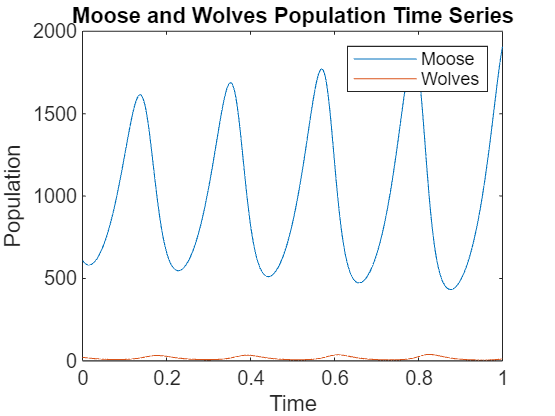

n=1000;
x=zeros(n,2);
x(1,:)=[610;22];
dt=0.1;
a=0.23; b=0.0133; c=0.4; d=0.0004;
for i=2:n
   x(i,1)=x(i-1,1)+(a*x(i-1,1)-b*x(i-1,1)*x(i-1,2))*dt;
   x(i,2)=x(i-1,2)+(-c*x(i-1,2)+d*x(i-1,1)*x(i-1,2))*dt;
end
times=linspace(0,1,n)';
plot(times,x)
xlabel("Time")
ylabel("Population");
title("Moose and Wolves Population Time Series");
legend("Moose",'Wolves')

## Question 4

clear;clc;
disp("Question 4")

Question 4


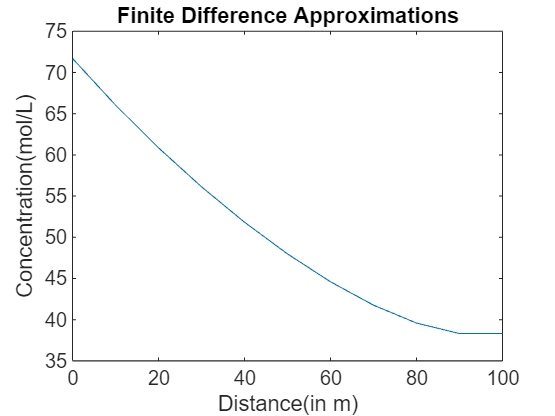

b=zeros(9,1);
D=5000;U=100;k=2;L=100;Cin=100;dx=10;
d1=D+U*dx;d2=(-2*D-k*dx*dx);d3=(D-U*dx);

d11=(-D-k*dx*dx);
d99=(-D-k*dx*dx-U*dx);
b1=-dx*U*Cin;
A=[d11 d3 0 0 0 0 0 0 0;
    d1 d2 d3 0 0 0 0 0 0;
    0 d1 d2 d3 0 0 0 0 0;
    0 0 d1 d2 d3 0 0 0 0;
    0 0 0 d1 d2 d3 0 0 0;
    0 0 0 0 d1 d2 d3 0 0;
    0 0 0 0 0 d1 d2 d3 0;
    0 0 0 0 0 0 d1 d2 d3;
    0 0 0 0 0 0 0 d1 d99];
b(1)=b1;
x=linspace(0,100,11);
y=zeros(11,1);
y(2:10)=(A\b)';
y(1)=(U*Cin*dx)/(U*dx+D)+(D*y(2))/(D+U*dx);
y(11)=y(10);
plot(x,y)
title("Finite Difference Approximations")
xlabel("Distance(in m)")
ylabel("Concentration(mol/L)")

## Question 5

clear;clc;
disp("Question 5")

Question 5


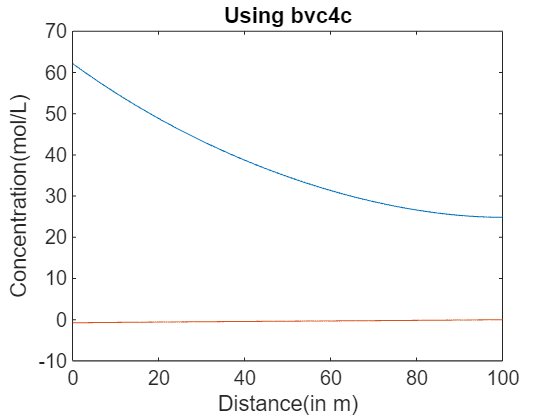

x=linspace(0,100,200);
solinit=bvpinit(x,[100 100]);
sol=bvp4c(@f5,@bcfun,solinit);
plot(sol.x,sol.y)
title("Using bvc4c");
xlabel("Distance(in m)")
ylabel("Concentration(mol/L)")

function res=bcfun(ya,yb)
        D=5000;U=100;Cin=100;
        res=[yb(2) D*ya(2)-U*ya(1)+U*Cin];
end
function dcdx=f5(~,y)
    D=5000;U=100;k=2;
    dcdx(1)=y(2);
    dcdx(2)=U/D*y(2)+k*y(1)/D;
end